# 第13章 PID控制器设计与应用

## 13.1 串联校正与反馈校正

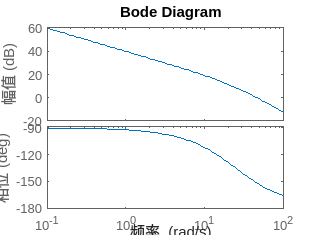

num1=[0 0 100];den1=[0.04 1 0]; %定义传递函数分子分母系数
G=tf(num1,den1); %建立传递函数数学模型G
w=logspace(-1,2,100); %定义ω范围
bode(G,w) %绘制伯德图

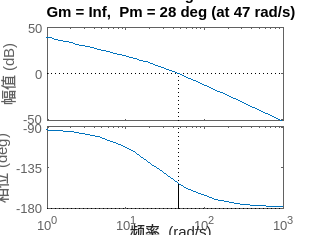

margin(G); %绘制带有所需幅值裕度和相角裕度的Bode图形

[gm,pm,wcg,wcp]=margin(G); %使用由Bode指令得到的幅值mag和相角phase及其频率值ω
[gm,pm,wcg,wcp]=margin(G)

gm = Inf

pm = 28.0202

wcg = Inf

wcp = 46.9782

close
clc
numc=[0.0262 1];denc=[0.0106 1]; %定义传递函数分子分母系数
Gc=tf(numc,denc) %建立传递函数数学模型Gc

Gc =
 
  0.0262 s + 1
  ------------
  0.0106 s + 1
 
连续时间传递函数。
模型属性


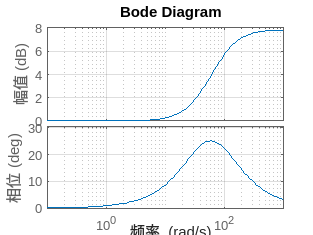

w=logspace(-1,3,100); %定义ω范围
figure(2) %在窗口2中绘制图形
bode(Gc,w);grid %绘制伯德图，添加栅格

G_o= Gc *G %建立传递函数数学模型G_o

G_o =
 
          2.62 s + 100
  -----------------------------
  0.000424 s^3 + 0.0506 s^2 + s
 
连续时间传递函数。
模型属性


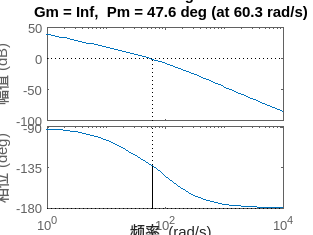

figure(3) %在窗口3中绘制图形
margin(G_o); %绘制带有所需幅值裕度和相角裕度的Bode图形

[gm,pm,wcg,wcp]=margin(G_o); %使用由Bode指令得到的幅值mag和相角phase及其频率值ω
[gm,pm,wcg,wcp]

ans =        Inf   47.5917       Inf   60.3251


G_1=feedback(G,1) %校正前系统单位负反馈

G_1 =
 
         100
  ------------------
  0.04 s^2 + s + 100
 
连续时间传递函数。
模型属性


G_o1=feedback(G_o,1) %校正后系统单位负反馈

G_o1 =
 
                2.62 s + 100
  ----------------------------------------
  0.000424 s^3 + 0.0506 s^2 + 3.62 s + 100
 
连续时间传递函数。
模型属性


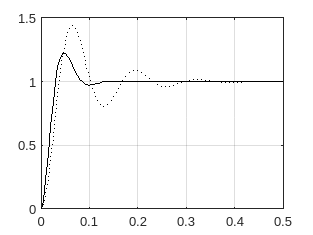

num=[0 0 100];den=[0.04 1 100]; %定义校正前传递函数分子分母系数
numd=[0 0 2.62 100];dend=[0.000424 0.0506 3.62 100];%定义校正后传递函数分子分母系数
t=0:0.005:0.5; %定义t的范围
figure(4); %在窗口4中绘制图形
[c1,x1,t]=step(num,den,t); %绘制出校正前阶跃响应曲线
[c2,x22,t]=step(numd,dend,t); %绘制出校正后阶跃响应曲线
plot(t,c1,':k',t,c2,'-k') %绘制曲线并标注曲线格式
grid

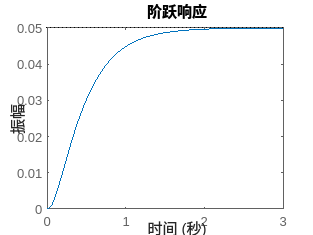

close
clc
num=[1];den=[1 10 20]; %定义传递函数的分子分母系数
sys=tf(num,den); %定义传递函数模型
step(sys); %未加入校正装置的系统开环阶跃响应

clc
close
sys = tf(1,conv([1 1],conv([2 1],conv([5 1],[10 1]))));
